# Transfer Learn from GoogLeNet

### Input

- `params` is a structure with fields from the Experiment Manager hyperparameter table.

### Output

- `trainDs` is an image datastore for the training data.

- `layers` is a layer graph that defines the neural network architecture.

- `options` is a `trainingOptions` object.

[trainDs, layers, options] = TransferLearning_setup1();

## Train the network

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:02 |        6.25% |       15.37% |       4.3495 |       2.6519 |          0.0010 |
|       1 |          50 |       00:08:19 |       34.38% |       54.09% |       1.5441 |       1.3294 |          0.0010 |
|       1 |         100 |       00:15:59 |       64.84% |       69.26% |       0.9724 |       0.8008 |          0.0010 |
|       1 |         150 |       00:23:15 |       78.91% |       73.94% |       0.6209 |   

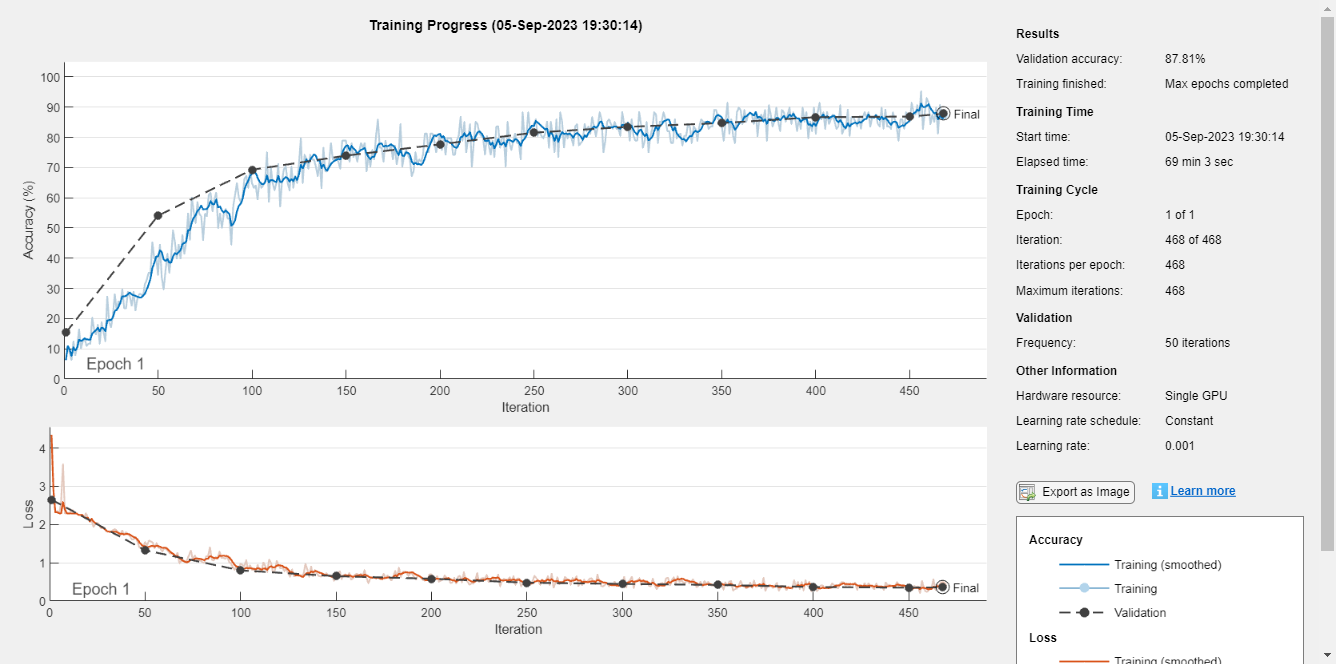

net = trainNetwork(trainDs, layers, options);

function [trainDs, layers, options] = TransferLearning_setup1()

#### Load Training Data

Load the training data and resize the images in a datastore. 

    data = load("../data/fashionMNIST.mat");
    yTrain = data.yTrain;
    yTest = data.yTest;
    
    xTrain = reshape(data.xTrain, 28, 28, 1, numel(yTrain));
    xTest = reshape(data.xTest, 28, 28, 1, numel(yTest));
    
    trainDs = augmentedImageDatastore([224 224], xTrain, yTrain, "ColorPreprocessing", "gray2rgb");
    testDs = augmentedImageDatastore([224 224], xTest, yTest, "ColorPreprocessing", "gray2rgb");

#### Define Network Architecture

Replace layers in GoogLeNet to perform transfer learning.

    net = googlenet;
    layers = layerGraph(net);
    newfc = fullyConnectedLayer(10);
    newclass = classificationLayer;
    
    layers = replaceLayer(layers, layers.Layers(end-2).Name, newfc);
    layers = replaceLayer(layers, layers.Layers(end).Name, newclass);

#### Specify Training Options

Call the [`trainingOptions`](matlab:doc('trainingOptions')) function to specify the training options for the experiment. Read the hyperparameters specified in Experiment Manager by accessing the fields of the input `params`. For example, access the initial learning rate `myInitialLearnRate` defined in the hyperparameter table with the argument value `params.myInitialLearnRate`.

    options = trainingOptions(  "adam", ...
                                "InitialLearnRate", 0.001,...
                                "MaxEpochs", 1, ... 
                                "ValidationData", testDs, ...
                                "Verbose", true, ...
                                "Plots", "training-progress");
end